## Program to **implement** contrast stretching of an image.

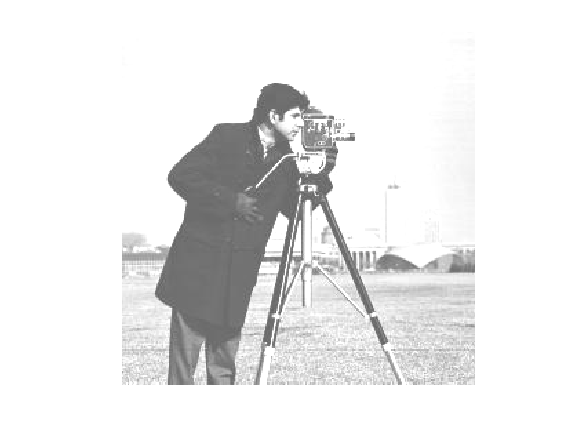

cm=imread('cameraman.tif');
[m,n]=size(cm);
a=100;
b=400;
c=min(min(cm));
d=max(max(cm));
for i=1:m
    for j=1:n
        arr(i,j)=((cm(i,j)-c)*((b-a)/(d-c)))+a;
    end
end
imshow(arr);

**CONTRAST STRETCHING (BUILT-IN FUNCTIONS)**

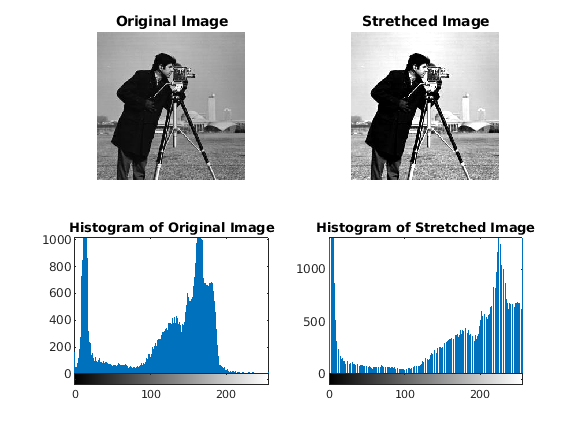

clf;
image = imread('cameraman.tif');
stretched_Image = imadjust(image, stretchlim(image, [0.05, 0.95]),[]);
 
subplot(2,2,1), imshow(image), title('Original Image');
subplot(2,2,2), imshow(stretched_Image), title('Strethced Image');
subplot(2,2,3), imhist(image), title('Histogram of Original Image');
subplot(2,2,4), imhist(stretched_Image), title('Histogram of Stretched Image');

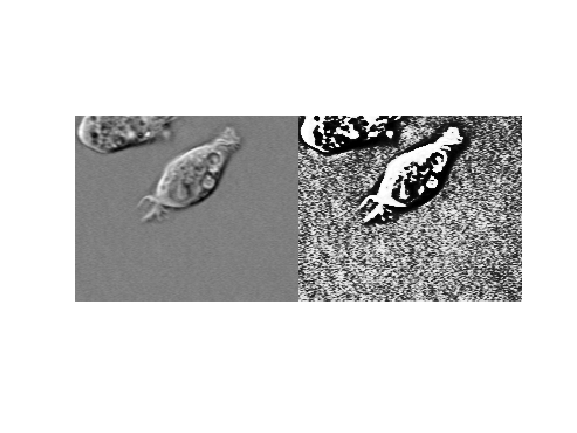

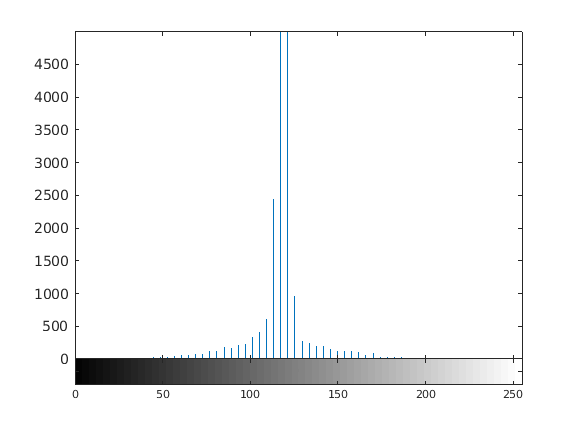

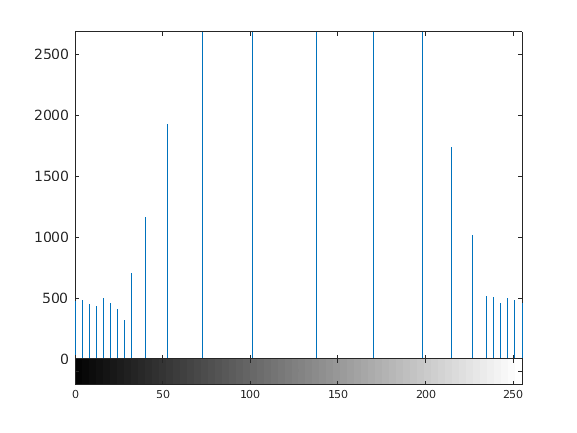

%Calling the ima function that is defined to get the contrast image.
ima('cell.tif');

## Power Law transformation of an image.

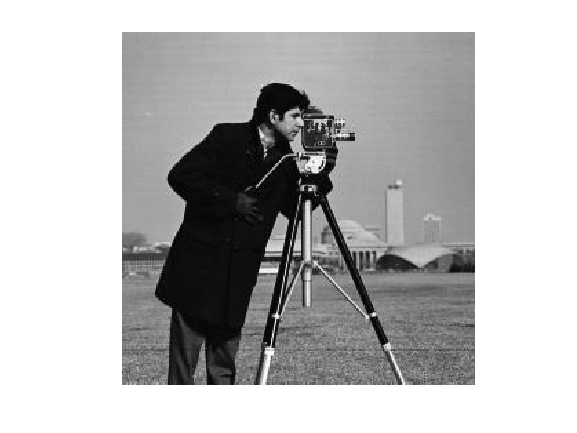

clf;
cm=imread('cameraman.tif');
[m,n]=size(cm);
c=1;
g=1;
for i=1:m
    for j=1:n
        arr(i,j)=c*(cm(i,j)^g);
    end
end
imshow(arr);

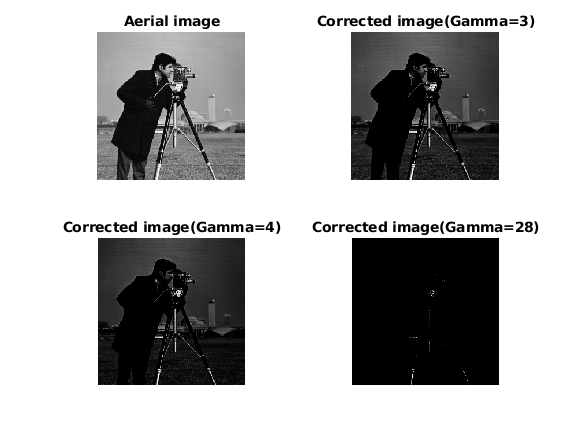

clf; 
c=1;
Gamma=[3,4,28];     
x=imread('cameraman.tif');
x1=double(x);      
y=c*(x1.^Gamma(1));                             % s=c*(r^ γ)
y1=c*(x1.^Gamma(2));
y2=c*(x1.^Gamma(3));
subplot(2,2,1),imshow(x), title('Aerial image')
subplot(2,2,2),imshow((y),[]), title('Corrected image(Gamma=3)')
subplot(2,2,3),imshow((y1),[]), title('Corrected image(Gamma=4)')
subplot(2,2,4),imshow((y2),[]), title('Corrected image(Gamma=28)')

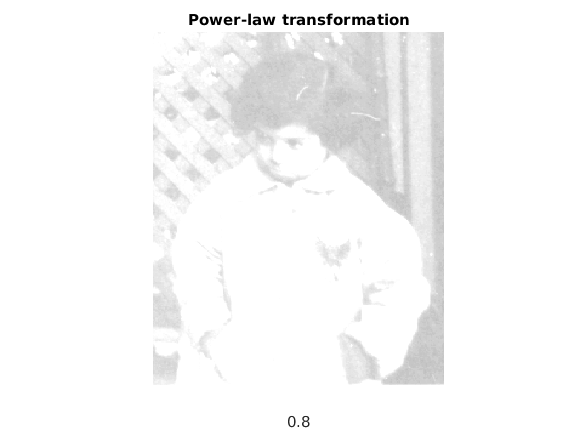

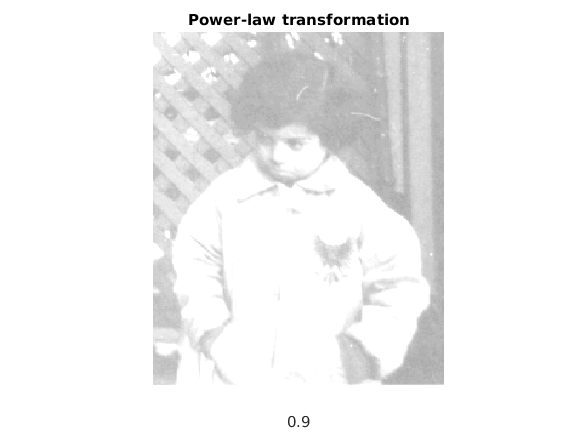

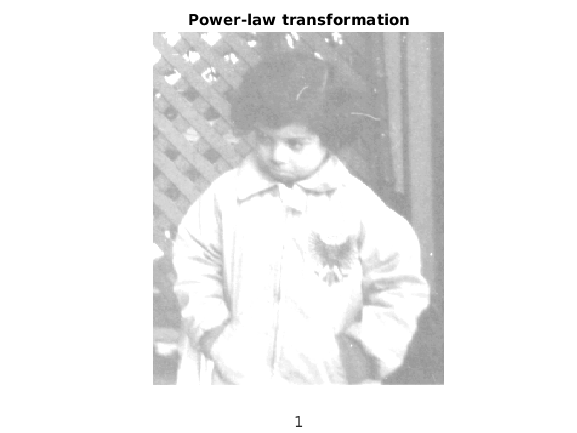

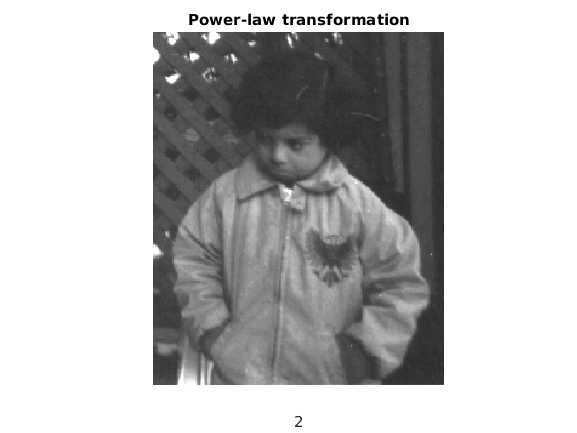

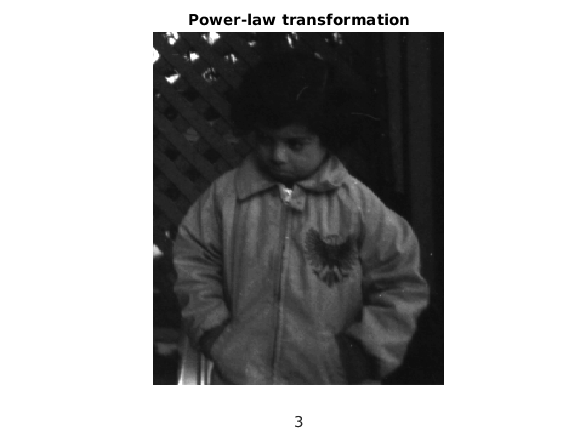

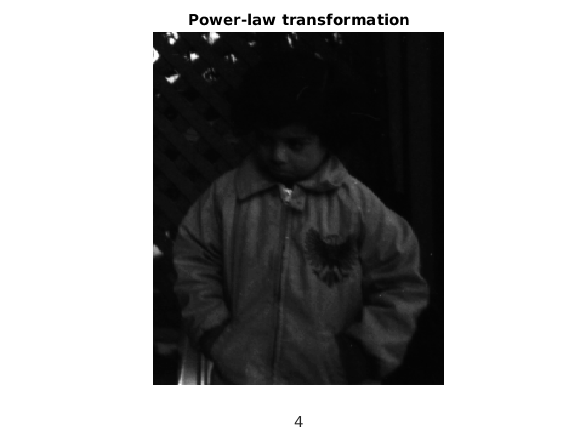

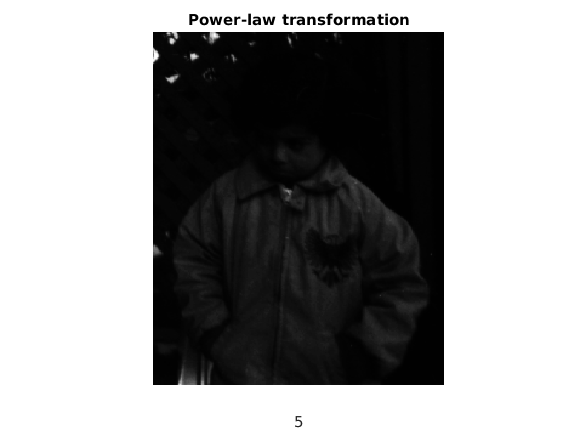

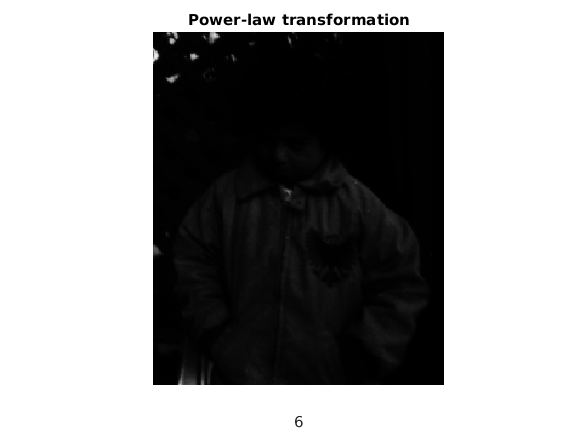

ans =     0.4196    0.4235    0.4196    0.4157    0.3882    0.3961    0.4000    0.4196    0.4196    0.4039    0.4392    0.6431    0.7843    0.7725    0.6667    0.7137    0.8353    0.8392    0.8314    0.7725    0.5373    0.4392    0.4314    0.4275    0.4392    0.4314    0.4196    0.4118    0.4157    0.4157    0.4196    0.4275    0.4235    0.4157    0.4157    0.4157    0.3882    0.3843    0.3882    0.3961    0.3882    0.4000    0.4039    0.4118    0.4039    0.4667    0.5765    0.8039    0.8000    0.8196
    0.4275    0.4157    0.4235    0.4196    0.4039    0.4000    0.4039    0.4314    0.4431    0.4235    0.5020    0.7137    0.8235    0.8235    0.7137    0.6510    0.7412    0.8235    0.8353    0.8235    0.6549    0.4667    0.4314    0.4235    0.4392    0.4314    0.4157    0.4157    0.4196    0.4196    0.4118    0.4196    0.4157    0.4196    0.4235    0.4196    0.4157    0.4000    0.3725    0.4039    0.4157    0.4235    0.4745    0.4706    0.4275    0.5020    0.6314    0.8157    0.8118   

%Calling the powtrans function that is defined to power transform the image
%on the set of gamma values
powtrans('pout.tif')

%powtrans function definition

function I=powtrans(X)
clf;
I=imread(X);
I=im2double(I);
[m ,n] = size(I);
c = 2;
g =[0.8 0.9 1 2 3 4 5 6]; % Gamma Correction Array
for r=1:length(g)
for p = 1 : m
    for q = 1 : n
        I3(p, q) = c * I(p, q).^ g(r);  
    end
end
figure, imshow(I3);title('Power-law transformation');xlabel('Gamma='),xlabel(g(r));
end
end


%ima function definition
function I=ima(X)
clf;
I = imread(X);
J = histeq(I);
imshowpair(I,J,'montage');
axis off;
figure
imhist(I,64);
figure
imhist(J,64);
end